# 2223-MA378 : Lab 2

Lab 2 of Numerical Analysis 2: Experiments with spline interpolation.

- **Name: Niall Madden **[*Change this to your name before submitting!!!!*] 

- **ID: **`01234567` [Change this to your ID]

- **Email: ** `n.madden321@universityofgalway.ie` [*Change this to your email address*]

- Date: Week 8, 2022/2023

- Upload your script with solutions to Exercises 0, 1, 2 and  3 Blackboard (2223-MA378... Labs ... Lab 2) by 5pm, Friday 10th March. Upload it as an .mlx or .pdf file (as you prefer).

## Exercise 0

Change the data at the start of this file to include your name, ID number and email address.

## A MATLAB primer

You are using a MATLAB "Live script". This is a note-book type interface for MATLAB (a bit like Jupyter) that let's us combine text and MATLAB code. You can run pieces of code one section at time (click on "Run Section") or run the entire notebook. For more on getting started with MATLAB, please work through the  MATLAB primer at [https://www.niallmadden.ie/2223-MA378/lab1/MA378_MATLAB_Primer.html](https://www.niallmadden.ie/2223-MA378/lab1/MA378_MATLAB_Primer.html)

## Outline

In class, we did a few examples of writing out piecewise polynomial interpolants of functions. However, in practice they are always implemented by computer. In this lab, we  will look at how this is done in MATLAB. Moreover, you will investigate how the numerical results compare with the theory. This has two purposes. 

- To verify that the theory is correct. This is of particular interest for the error estimate given for cubic splines since they  were presented without proof.

- More important) to verify that the theory is *sharp*. For example, we might prove that the error for piecewise linear interpolation is bounded by $Ch^2$, for some constant $C$ , but this does not exclude the possibility that in fact it can be bounded by $Ch^3$. However this is easily verified experimentally.

## Some Spline  Basics

Let $\{ x_i\}_{i=0}^N := \{x_0 < x_1 < \dots < x_N\}$ be a set of interpolation points.  The *piecewise linear interpolant*, $l$, of a function $f$ at those points is defined as follows 

- $l$ is continuous on $[x_0,x_N]$,

- $l$ is linear (i.e., a polynomial of degree 1), denoted $l_i$, on each subinterval $[x_{i-1}, x_i]$, for $i=1, \dots, N$.

- $l(x_i) = f(x_i)$ on each $i=0, \dots, N$.

Revise your notes from Section 2.1 to see how to write down a formula for $l_i$,  the restriction of $l$ to the interval  $[x_{i-1}, x_i]$. We also proved that $\| f - l \|_\infty \leq \frac{h^2}{8}\|f''\|_\infty$ where  $h = x_{i} - x_{i-1}%$, and the norm $\|\cdot\|_\infty$ means $\| u\|_\infty := \max_{x_0 \leq x \leq x_N} |u(x)|$.

## Computing Piecewise Polynomial Interpolants

In MATLAB, the function` interp1() `computes various types of piecewise polynomial interpolanrs to a data set. The syntax for computing the piecewise linear interpolant to the data set $\{(x(1), y(1)), (x(2), y(2)), ... (x_N, y_N)\}$ is:

where $x$ is a vector of strictly increasing points, and $y$ is a vector of the same length as $x$. The function returns a structure representing a piecewise polynomial. It can then be evaluated using the `ppval()` function.

### Example

Let's compute the piecewise linear interpolant to the points $\{ (0,0), (1,1), (2,1), (3,6), (4,5)\}$.

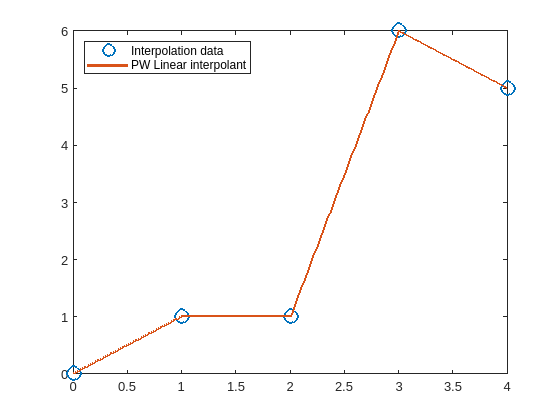

x = [0, 1, 2, 3, 4]; % interpolation points
y = [0, 1, 1, 6, 5]; % interpolation values
l = interp1(x,y,'linear', 'pp');
xp = x(1):0.01:x(end) ; % points at which we'll plot l.

plot(x,y, 'o', xp, ppval(l, xp), 'MarkerSize', 10, 'LineWidth',2);
legend('Interpolation data', 'PW Linear interpolant', 'Location','northwest')

## Interpolating a function

Let's interpolate $f(x)=\sin(\pi x)%$ on $[0,1]$ with $N=4$. 

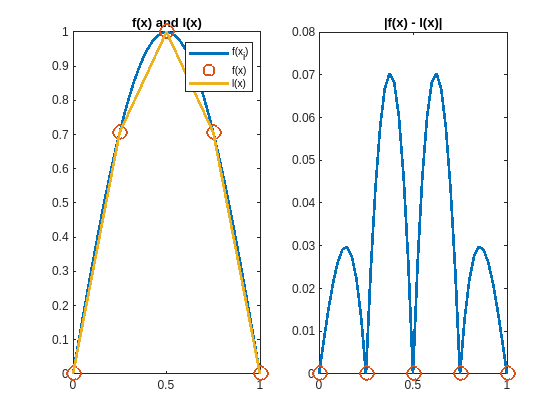

f = @(x)sin(pi*x);
N = 4;
h = 1/N;
x = 0:h:1;

l = interp1(x, f(x), 'linear', 'pp');
xp = 0:h/10:1;
figure(1); subplot(1,2,1)
plot(xp, f(xp), x, f(x), 'o', ...
   xp, ppval(l, xp), 'MarkerSize', 10, 'LineWidth',2);
legend('f(x_i)', 'f(x)', 'l(x)')
title('f(x) and l(x)');
subplot(1,2,2)
plot(xp, abs(f(xp)-ppval(l, xp)), x, x*0, 'o', 'MarkerSize', 10, 'LineWidth',2);
title('|f(x) - l(x)|');

error=max(abs(f(xp)-ppval(l, xp)));
fprintf('N=%4d, h=%8.2e, ||f-l||=%9.3e\n', N , h, error); 

N=   4, h=2.50e-01, ||f-l||=7.033e-02


Test the code above, and verify that, as $N$ increases, the error decreses. We'll do this in a more systematic way in the next section.

## Verifying Convergence

We'll verify that the method converges at a rate that is proportional to $h^2 = N^{-2}$. For that, we'll use a for loop:

k=0;
Ns = [4, 8, 16, 32, 64, 128, 256, 512, 2014]; % the values of $N$ we'll use
for N=Ns
   k=k+1;
   h = 1/N;
   x = 0:h:1;
   l = interp1(x, f(x), 'linear', 'pp');
   xp = 0:h/10:1;
   Errors(k)=max(abs(f(xp)-ppval(l, xp)));
   fprintf('N=%4d, h=%8.2e, ||f-l||=%9.3e\n', Ns(k) , h, Errors(k));
end

N=   4, h=2.50e-01, ||f-l||=7.033e-02
N=   8, h=1.25e-01, ||f-l||=1.885e-02
N=  16, h=6.25e-02, ||f-l||=4.792e-03
N=  32, h=3.12e-02, ||f-l||=1.203e-03
N=  64, h=1.56e-02, ||f-l||=3.011e-04
N= 128, h=7.81e-03, ||f-l||=7.529e-05
N= 256, h=3.91e-03, ||f-l||=1.882e-05
N= 512, h=1.95e-03, ||f-l||=4.706e-06
N=2014, h=4.97e-04, ||f-l||=3.042e-07


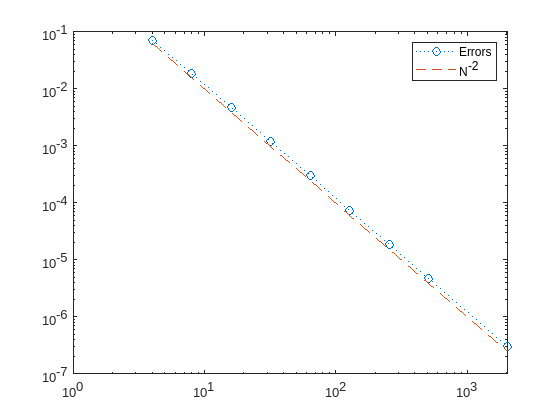

subplot(1,1,1);loglog(Ns, Errors, ':o', Ns, Ns.^(-2), '--');
legend('Errors', 'N^{-2}')

You should observe that, in this log-log plot, the lines representing the errors and $N^{-2}$ are parallel. This implies that, indeed, the error is proportional to $h^2$. 

### **EXERCISE 1** : Find C

We expect that the error is (approximately) $Ch^2$. Use the data above to estimate $C$. Use that value of $C$ to determine the value of $N$ you'd need to take to ensure that the error is no more than $10^{-12}$. Show your calcuations in MATLAB. 

**YOUR CODE GOES HERE:**

## Cubic Spline Interpolant

The `interp1()` function can also compute the natural cubic spline interpolant to a set of data. The syntax as

This is slightly different from the natural cubic spline we studied in class: instead of ensuring that $S''(x_0)=S''(x_N)=0$, it uses the "not-a-knot" condition. 

### Example

Let's compute the cubic spline interpolant to the points $\{ (0,0), (1,1), (2,1), (3,6), (4,5)\}$.

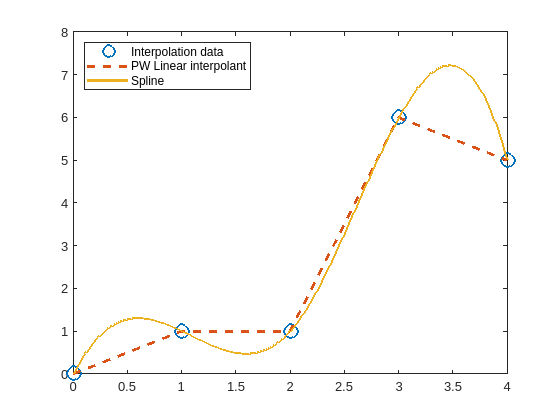

x = [0, 1, 2, 3, 4]; % interpolation points
y = [0, 1, 1, 6, 5]; % interpolation values
l = interp1(x,y,'linear', 'pp');
S = interp1(x,y,'spline', 'pp');

xp = x(1):0.01:x(end) ; % points at which we'll plot l.

plot(x,y, 'o', ...
   xp, ppval(l, xp), '--', ...
   xp, ppval(S, xp), 'MarkerSize', 10, 'LineWidth',2);
legend('Interpolation data', 'PW Linear interpolant', 'Spline', 'Location','northwest')

### EXERCISE 2: Verify convergence

Taking $f=\sin(\pi x)$ and $x_0=0$, $x_N=1$, verify that $\| f - S \|_\infty \leq C h^4$, and estimate the value of $C$. Do this by producing a log-log plot of $\|f-S\|_\infty$ against $N$.

## How accurate is PCHIP interpolation?

At the end of Chapter 2, we studied piecewise Cubic Hermite Interpolation (*the "PCHIP" method*). We learned that the error is proportional to $h^4$. In MATLAB, you can compute a pchip interpolant using 

However, this is not the real *PCHIP* interpolant.  That requires but just the values for $H(x)$ at interpolation points, but also $H'(x)$. As a result, we cannot be certain that it will have an error that is proportional to $h^4$. 

### EXERCISE 3: Determine the order of accuracy of MATLAB's `pchip` method.

Using a approach similar to how we verified the order of convergence of the '`linear`' and '`spline`' methods, determine the order of accuracy of the '`pchip`' method.